# Супер-пупер скрипт для лабок по общесосу

clear variables
close all

## Вводим столбец значений по оси абсцисс

prompt = 'Please, enter the name of file containig X values(using .csv) \n';
filename = input(prompt, 's');
x_colomn = importdata(filename);

## Вводим столбец значений по оси ординат

prompt = 'Please, enter the name of file containig Y values(using .csv) \n';
filename = input(prompt, 's');
y_colomn = importdata(filename);
clc;

## Считаем всё по МНК

MV = medium_values(x_colomn, y_colomn);
SSQ = smallest_squares_method(x_colomn, y_colomn, 1); % используем свою функцию, потому что потом можно будет прикрутить всё к ней
SSQ_delta = smallest_squares_method_delta(MV, SSQ, size(x_colomn, 1));

## А это тест

%TEST
% x = (1:10)';
% y1 = x + randn(10,1);

% MV = medium_values(x, y1);
% SSQ = smallest_squares_method(x, y1, 1);
% SSQ_delta = smallest_squares_method_delta(MV, SSQ, size(x, 1));
%END OF TEST

## А это построение графика

надо запилить функцию с вводом параметров построения

%MAKE A FUNCTION
prompt = {'Please, enter the name of scatter plot color: (default values are recommended)', 'Please, enter the name of scatter type: (default values are recommended)'}

prompt = 1×2 cell array
    {'Please, enter the name of scatter plot color: (default values are recommended)'}    {'Please, enter the name of scatter type: (default values are recommended)'}


scatter_info = inputdlg(prompt, 'Scatter info', [1 50; 1 50], {'blue', '.'})

scatter_info = 2×1 cell array
    {'blue'}
    {'.'   }


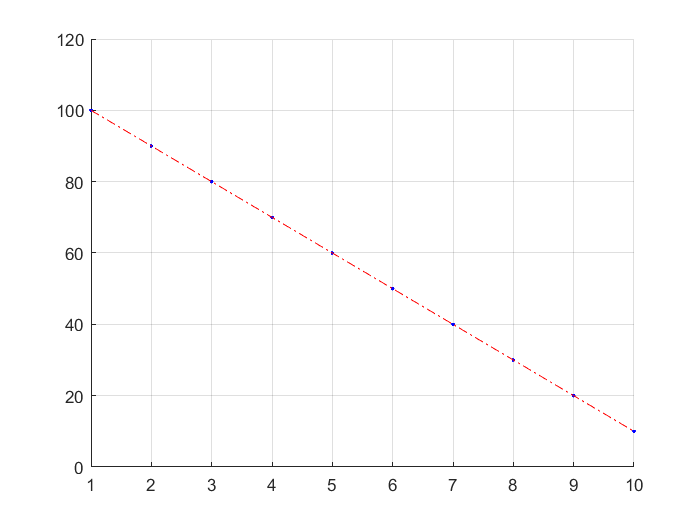

scatter(x_colomn, y_colomn, 25, string(scatter_info(1)), string(scatter_info(2)));
yfit = SSQ(1)*x_colomn+SSQ(2);
hold on;
plot(x_colomn, yfit, 'r-.');
grid on
hold off;

## Таблицы необходимых подсчётов

%T = table(MV);

T = table
                    MV                 
    ___________________________________

    5.5      55     220    38.5    3850


%T

T = table
                    MV                 
    ___________________________________

    5.5      55     220    38.5    3850
